# HW3

clc;clear;close all;
% syms l1 l2 h m1 m2 m_d4 M g theta1 theta2 d4 dtheta1 dtheta2 dd4
% q=[theta1 theta2 d4];
% q_dot=[dtheta1 dtheta2 dd4];
global l2 h m1 m2 m_d4 M g rho d l
rho= 7800;
d=0.015;
l=0.2;
l2=0.2; 
h=0.1; 
g=9.81;
M=0.5;
m1=pi*d^2/4*h*rho;
m2=pi*d^2/4*l2*rho;
m_d4=pi*d^2/4*l*rho; 
para=[m1 m2 m_d4 M g h l2 l ];
q = rand(1,3);
q_dot = rand(1,3);
[H,C,G] = dynamics_mat(q,q_dot,para);

$$A01 = \left(\begin{array}{cccc} \frac{2593346024722575}{4503599627370496} & 0 & \frac{7363957088334311}{9007199254740992} & 0\\ \frac{7363957088334311}{9007199254740992} & 0 & -\frac{2593346024722575}{4503599627370496} & 0\\ 0 & 1 & 0 & \frac{1}{10}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

disp(H);disp(C);disp(G);

$$\left(\begin{array}{ccc} \frac{375388650410116316582046858162493691941124181815051153610533686679247242720108591522397613975044207\,\pi }{546812681195752981093125556779405341338292357723303109106442651602488249799843980805878294255763456000}+\frac{395116790029233119615020048429343361526960782195026056419306836612418189166286072494849429582110820710662119123227}{19701003098197239606139520050071806902539869635232723333974146702122860885748605305707133127442457820403313995153408} & \frac{945131906056223141399482682800796693715146811439880705010220991613877554990844742900348839529829}{2187250724783011924372502227117621365353169430893212436425770606409952999199375923223513177023053824} & \frac{1}{288230376151711744}\\ \frac{945131906056223141399482682800796693715146811439880705010220991613877554990844742900348839529829}{2187250724783011924372502227117621365353169430893212436425770606409952999199375923223513177023053824} & \frac{113906012334107784868092650575829967\,\pi }{129807421463370690713262408230502400000}+\frac{96343654263783963608561116894955535873079325163697576883816334060976867679086197787}{242833611528216133864932738352939863330300854881517440156476551217363035650651062272} & \frac{351\,\pi }{20000}+\frac{1}{10}\\ \frac{1}{288230376151711744} & \frac{351\,\pi }{20000}+\frac{1}{10} & \frac{351\,\pi }{4000}+\frac{1}{2} \end{array}\right)$$

    0.0818    0.0120    0.0072
   -0.0120    0.4674    0.2153
   -0.0072   -0.2153         0

   -0.4324
   -4.3047
   -2.9024



## Q2

clc;clear;close all;
T = 2;
n = 200;

tao=zeros(3,2000);
tau = tau_plan(T, n);    

PIH =      0     0


$$H = \left(\begin{array}{ccc} 0.041 & -0.0001 & 0\\ -0.0001 & 0.0761 & 0.1551\\ 0 & 0.1551 & 0.7757 \end{array}\right)$$

C =    -0.0124    0.0242   -0.0090
   -0.0242   -0.0287    0.0510
    0.0090   -0.0510         0


G =     0.8666
   -1.3553
    0.6176


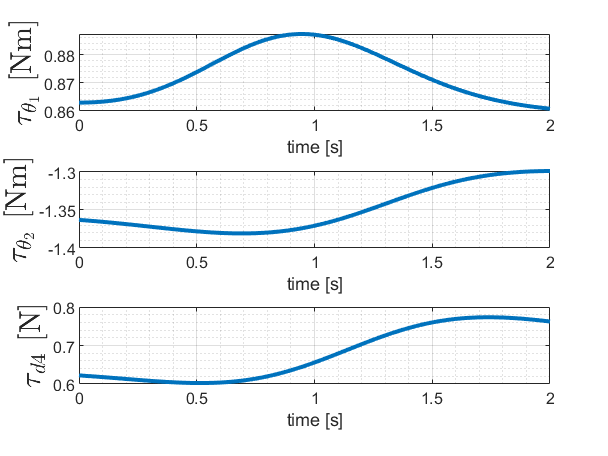



t = linspace(0, T, n);


figure(1)
subplot(3,1,1)
plot(t,tau(1,:),'linewidth',2)
grid on; grid minor;
xlabel('time [s]')
ylabel('$\tau_{\theta_1}$ [Nm]','interpreter','latex','fontsize',15)
subplot(3,1,2)
plot(t,tau(2,:),'linewidth',2)
grid on; grid minor;
xlabel('time [s]')
ylabel('$\tau_{\theta_2}$ [Nm]','interpreter','latex','fontsize',15)
subplot(3,1,3)
plot(t,tau(3,:),'linewidth',2)
grid on; grid minor;
xlabel('time [s]')
ylabel('$\tau_{d4}$ [N]','interpreter','latex','fontsize',15)
saveas(gcf, 'q2','png')

## Q3

clc;clear;close all;
global l2 l3 h m1 m2 m_d4 M g rho d l
rho= 7800;
d=0.015;
l=0.2;
l2=0.2; 
h=0.1; 
g=9.81;
M=0.5;
m1=pi*d^2/4*h*rho;
m2=pi*d^2/4*l2*rho;
m_d4=pi*d^2/4*l*rho; 
para=[m1 m2 m_d4 M g h l2 l ];

PROFILE = 'constant';
T = 2;
n = 20;
h = 0.1;
l2 = 0.2;
l3 = 0;
params = [h,l2,l3];
x_init = [0.1, 0.2, 0.35]';
x_fin = [0.3, -0.1, 0.15]';
x = x_plan(PROFILE, T, n, x_init, x_fin);
v = v_plan(PROFILE, T, n, x_init, x_fin);
a = a_plan(PROFILE, T, n, x_init, x_fin);

q_ = q_plan(x, [1,1], params)

q_ =     1.1071    1.0304    0.9476    0.8593    0.7665    0.6705    0.5730    0.4757    0.3805    0.2890    0.2023    0.1214    0.0465   -0.0222   -0.0849   -0.1419   -0.1936   -0.2405   -0.2831   -0.3218
   -0.0909   -0.0603   -0.0319   -0.0069    0.0132    0.0267    0.0317    0.0266    0.0097   -0.0201   -0.0631   -0.1185   -0.1847   -0.2591   -0.3390   -0.4217   -0.5046   -0.5860   -0.6645   -0.7392
    0.2693    0.2520    0.2354    0.2198    0.2053    0.1921    0.1806    0.1711    0.1639    0.1593    0.1577    0.1590    0.1632    0.1701    0.1794    0.1907    0.2037    0.2180    0.2336    0.2500


q_dot_ = q_dot_plan(q_, v, T, 'analytical', params);
q_dot2_ = q_dot2_plan(q_, q_dot_, a, T,'analytical', params);

for j=1:1:20
    q = q_(:,j);
    q_dot = q_dot_(:,j);
    q_dot2= q_dot2_(:,j);
   % Forward recursion  
   [omega,alpha,ae,ac] = forward_recursion(q, q_dot, q_dot2,para);
    
   % Backward recursion
    [f] = backward_recursion(ac,ae,q,para);
     [Mo] = backward_recursion_M(ac,ae,q,para,alpha,omega);
   f3(:,j)=f(:,4);
   f2(:,j)=f(:,3);
   M2(:,j)=Mo(:,3);
   M1(:,j)=Mo(:,2);
end
f3

f3 =     0.2735    0.2211    0.1516    0.0699   -0.0151   -0.0904   -0.1396   -0.1445   -0.0875    0.0444    0.2568    0.5449    0.8933    1.2792    1.6773    2.0648    2.4247    2.7461    3.0242    3.2584
    0.3926    0.2426    0.1118    0.0082   -0.0613   -0.0930   -0.0876   -0.0519    0.0018    0.0570    0.0963    0.1042    0.0705   -0.0084   -0.1299   -0.2868   -0.4695   -0.6680   -0.8733   -1.0781
    4.8882    4.9042    4.9184    4.9326    4.9487    4.9687    4.9935    5.0231    5.0552    5.0847    5.1035    5.1005    5.0648    4.9883    4.8676    4.7047    4.5055    4.2784    4.0322    3.7754


f2

f2 =     0.0416    0.0740    0.0836    0.0716    0.0428    0.0051   -0.0300   -0.0493   -0.0395    0.0099    0.1039    0.2404    0.4096    0.5970    0.7868    0.9653    1.1232    1.2554    1.3606    1.4398
    0.3926    0.2426    0.1118    0.0082   -0.0613   -0.0930   -0.0876   -0.0519    0.0018    0.0570    0.0963    0.1042    0.0705   -0.0084   -0.1299   -0.2868   -0.4695   -0.6680   -0.8733   -1.0781
    7.5673    7.5895    7.6082    7.6256    7.6446    7.6678    7.6968    7.7314    7.7685    7.8009    7.8167    7.8008    7.7378    7.6160    7.4302    7.1827    6.8818    6.5391    6.1676    5.7793


M2

M2 =     0.0784    0.0484    0.0222    0.0015   -0.0124   -0.0187   -0.0175   -0.0103    0.0005    0.0117    0.0196    0.0212    0.0144   -0.0014   -0.0257   -0.0572   -0.0938   -0.1335   -0.1746   -0.2156
   -0.0313   -0.0292   -0.0231   -0.0136   -0.0021    0.0093    0.0178    0.0203    0.0137   -0.0044   -0.0351   -0.0776   -0.1295   -0.1870   -0.2459   -0.3026   -0.3545   -0.4000   -0.4384   -0.4698
         0         0         0         0         0   -0.0000   -0.0000         0   -0.0000         0         0         0         0         0         0         0         0         0         0         0


M1

M1 =     0.0784    0.0484    0.0222    0.0015   -0.0124   -0.0187   -0.0175   -0.0103    0.0005    0.0117    0.0196    0.0212    0.0144   -0.0014   -0.0257   -0.0572   -0.0938   -0.1335   -0.1746   -0.2156
    1.7510    1.7582    1.7684    1.7815    1.7969    1.8131    1.8275    1.8371    1.8381    1.8266    1.7986    1.7516    1.6844    1.5981    1.4956    1.3810    1.2588    1.1334    1.0082    0.8861
   -0.0785   -0.0485   -0.0224   -0.0016    0.0123    0.0186    0.0175    0.0104   -0.0004   -0.0114   -0.0193   -0.0208   -0.0141    0.0017    0.0260    0.0574    0.0939    0.1336    0.1747    0.2156


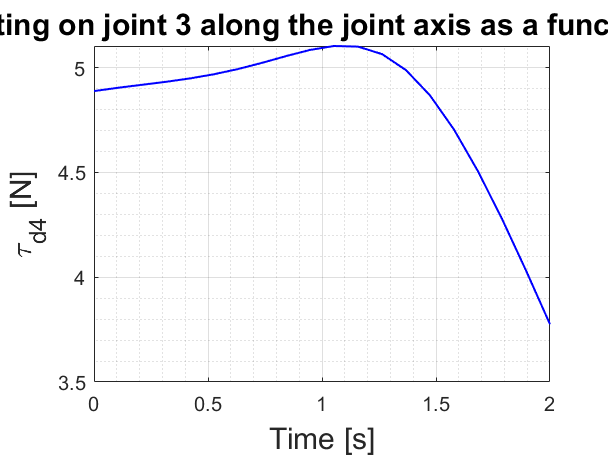

t = linspace(0, T, n);
plot(t,f3(3,:),'b-','linewidth',1)
grid on; grid minor;
xlabel('Time [s]','interpreter','tex','fontsize',15)
ylabel('\tau_{d4} [N]','interpreter','tex','fontsize',15)
title('Force acting on joint 3 along the joint axis as a function of time','fontsize',15)
saveas(gcf, 'q3','png')

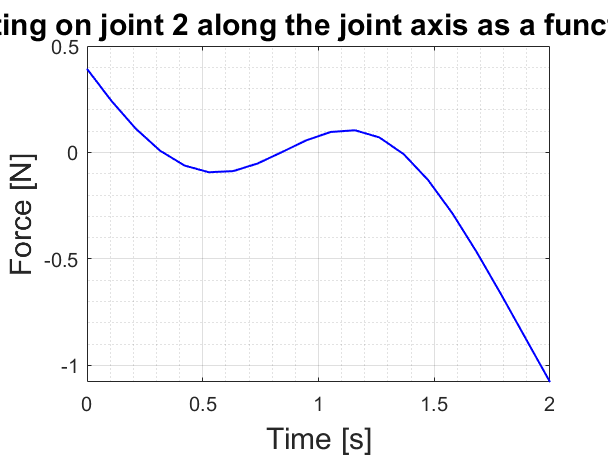


plot(t,f2(2,:),'b-','linewidth',1)
grid on; grid minor;
xlabel('Time [s]','interpreter','tex','fontsize',15)
ylabel('Force [N]','interpreter','tex','fontsize',15)
title('Force acting on joint 2 along the joint axis as a function of time','fontsize',15)
saveas(gcf, 'q3','png')

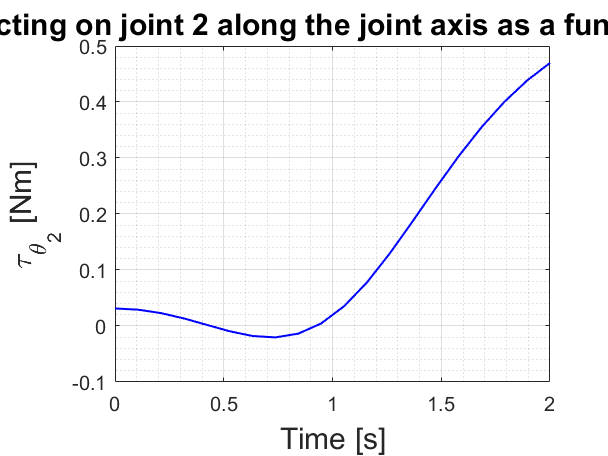


t = linspace(0, T, n);
plot(t,-M2(2,:),'b-','linewidth',1)
grid on; grid minor;
xlabel('Time [s]','interpreter','tex','fontsize',15)
ylabel('\tau_{\theta_2} [Nm]','interpreter','tex','fontsize',15)
title('torque acting on joint 2 along the joint axis as a function of time','fontsize',15)
saveas(gcf, 'q3','png')

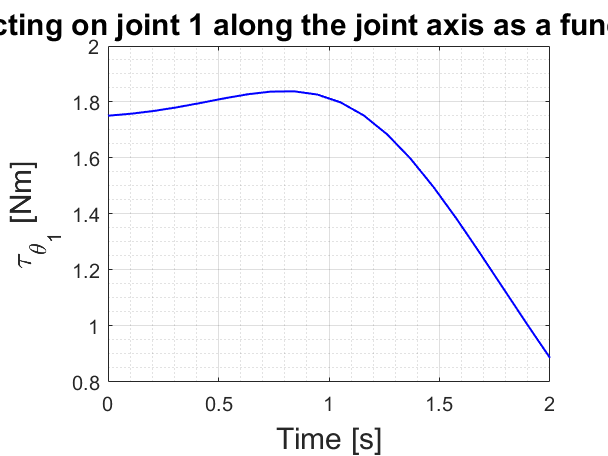

$$\left(\begin{array}{cccc} \cos\left(\theta_{1}\right) & 0 & \sin\left(\theta_{1}\right) & 0\\ \sin\left(\theta_{1}\right) & 0 & -\cos\left(\theta_{1}\right) & 0\\ 0 & 1 & 0 & \frac{1}{10}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\left(\begin{array}{cccc} \cos\left(\theta_{2}\right) & 0 & -\sin\left(\theta_{2}\right) & l_{2}\,\cos\left(\theta_{2}\right)\\ \sin\left(\theta_{2}\right) & 0 & \cos\left(\theta_{2}\right) & l_{2}\,\sin\left(\theta_{2}\right)\\ 0 & -1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & d_{4}+l_{3}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$A01 = \left(\begin{array}{cccc} \cos\left(\theta_{1}\right) & 0 & \sin\left(\theta_{1}\right) & 0\\ \sin\left(\theta_{1}\right) & 0 & -\cos\left(\theta_{1}\right) & 0\\ 0 & 1 & 0 & \frac{1}{10}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$A02 = \left(\begin{array}{cccc} \cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right) & -\sin\left(\theta_{1}\right) & -\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) & l_{2}\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\\ \cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right) & -\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) & l_{2}\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\\ \sin\left(\theta_{2}\right) & 0 & \cos\left(\theta_{2}\right) & l_{2}\,\sin\left(\theta_{2}\right)+\frac{1}{10}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$A03 = \left(\begin{array}{cccc} \cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right) & -\sin\left(\theta_{1}\right) & -\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) & l_{2}\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)-\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\left(d_{4}+l_{3}\right)\\ \cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right) & -\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) & l_{2}\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)-\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\left(d_{4}+l_{3}\right)\\ \sin\left(\theta_{2}\right) & 0 & \cos\left(\theta_{2}\right) & \cos\left(\theta_{2}\right)\,\left(d_{4}+l_{3}\right)+l_{2}\,\sin\left(\theta_{2}\right)+\frac{1}{10}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$R01 = \left(\begin{array}{ccc} \cos\left(\theta_{1}\right) & 0 & \sin\left(\theta_{1}\right)\\ \sin\left(\theta_{1}\right) & 0 & -\cos\left(\theta_{1}\right)\\ 0 & 1 & 0 \end{array}\right)$$

JL_t = 1×2 cell array
    {0×0 double}    {3×3 sym}



t = linspace(0, T, n);
plot(t,M1(2,:),'b-','linewidth',1)
grid on; grid minor;
xlabel('Time [s]','interpreter','tex','fontsize',15)
ylabel('\tau_{\theta_1} [Nm]','interpreter','tex','fontsize',15)
title('torque acting on joint 1 along the joint axis as a function of time','fontsize',15)
saveas(gcf, 'q3','png')